# Chap 2 - Messages history

loadenv("../.env");
modelName = "gpt-4o-mini";
chat = openAIChat("You are a MATLAB expert.",ModelName=modelName);

The message history is structured as follow

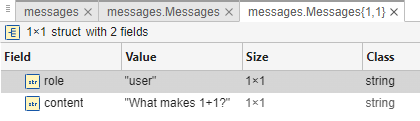

messages = messageHistory;
query = "What makes 1+1?";
messages = addUserMessage(messages, query)

messages =   messageHistory with properties:

    Messages: {[1×1 struct]}


messages.Messages{1}

ans = struct with fields:
       role: "user"
    content: "What makes 1+1?"


[text, response] = generate(chat, messages);
messages = addResponseMessage(messages, response)

messages =   messageHistory with properties:

    Messages: {[1×1 struct]  [1×1 struct]}


messages.Messages{2}

ans = struct with fields:
       role: "assistant"
    content: "In mathematics, \(1 + 1\) equals \(2\). This is a basic arithmetic operation where you are adding the number one to itself, resulting in two."


% Extract the cell array of structs
msgCells = messages.Messages;

% Concatenate the cell array into a struct array
msgStructArray = [msgCells{:}];

% Convert the struct array into a table
T = struct2table(msgStructArray)

T = 2×2 table
       role                                                                            content                                                                    
    ___________    _______________________________________________________________________________________________________________________________________________

    "user"         "What makes 1+1?"                                                                                                                              
    "assistant"    "In mathematics, \(1 + 1\) equals \(2\). This is a basic arithmetic operation where you are adding the number one to itself, resulting in two."
